# Figure S4: Other Slice Dirs

clear

## 1. Select background parameters

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision/MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/HPCData/FigureD4/'];
addpath(DataFolder)

ParName = {'S_EE','S_EI','S_IE','S_II',...
           'S_Elgn', 'S_Ilgn', 'rI_L6'};
ParNameShow = {'S^{EE}','S^{EI}','S^{IE}','S^{II}',...
               'S^{Elgn}', 'S^{Ilgn}', 'F^{IL6}'};

rE_L6 = 0.25; % rI_L6 to be determined
% Free pars: Fix or Range:in order of SEE SEI SIE SII
%                                     SELGN SILGN FIL6 1-7
GridNum = 160; %160
FreeParFix = {0.024, 0.0362, 0.0176, 0.120,...
              0.048, 0.096, 0.75};
SEERan = [0.018,0.030];
SIIRan = [0.08, 0.20];
S_EI_Mtp = [0.9, 2.4];  % of S_EE
S_IE_Mtp = [0.1, 0.25]; % of S_II 
S_Elgn_Mtp = [1.5 3.0]; % of S_EE
S_Ilgn_Mtp = [1.5 3];   % of S_Elgn
rI_L6_Mtp  = [1.5 3 4.5 6]; % of rE_L6
FreeParRan = {linspace(SEERan(1),              SEERan(2),               GridNum), ...% SEE
              linspace(SEERan(1)*S_EI_Mtp(1),  SEERan(2)*S_EI_Mtp(2),   GridNum), ...% SEI
              linspace(SIIRan(1)*S_IE_Mtp(1),  SIIRan(2)*S_IE_Mtp(2),   GridNum), ...% SIE
              linspace(SIIRan(1),              SIIRan(2),               GridNum), ...% SII
              linspace(SEERan(1)*S_Elgn_Mtp(1),SEERan(2)*S_Elgn_Mtp(2), GridNum), ...% SElgn
              linspace(SEERan(1)*S_Elgn_Mtp(1)*S_Ilgn_Mtp(1),...
                                               SEERan(2)*S_Elgn_Mtp(2)*S_Ilgn_Mtp(2), GridNum), ...% SElgn
              linspace(SEERan(1)*rI_L6_Mtp(1), SEERan(2)*rI_L6_Mtp(2),  GridNum)} ;  %FIL6 

ParInd1=[1 3 5 1 3 6];
ParInd2=[2 4 6 5 6 7];
Panel1 = 2; Panel2 = 3;

## 4. Good Areas

white frE = [3 5], frI/frE = (3, 4.25)

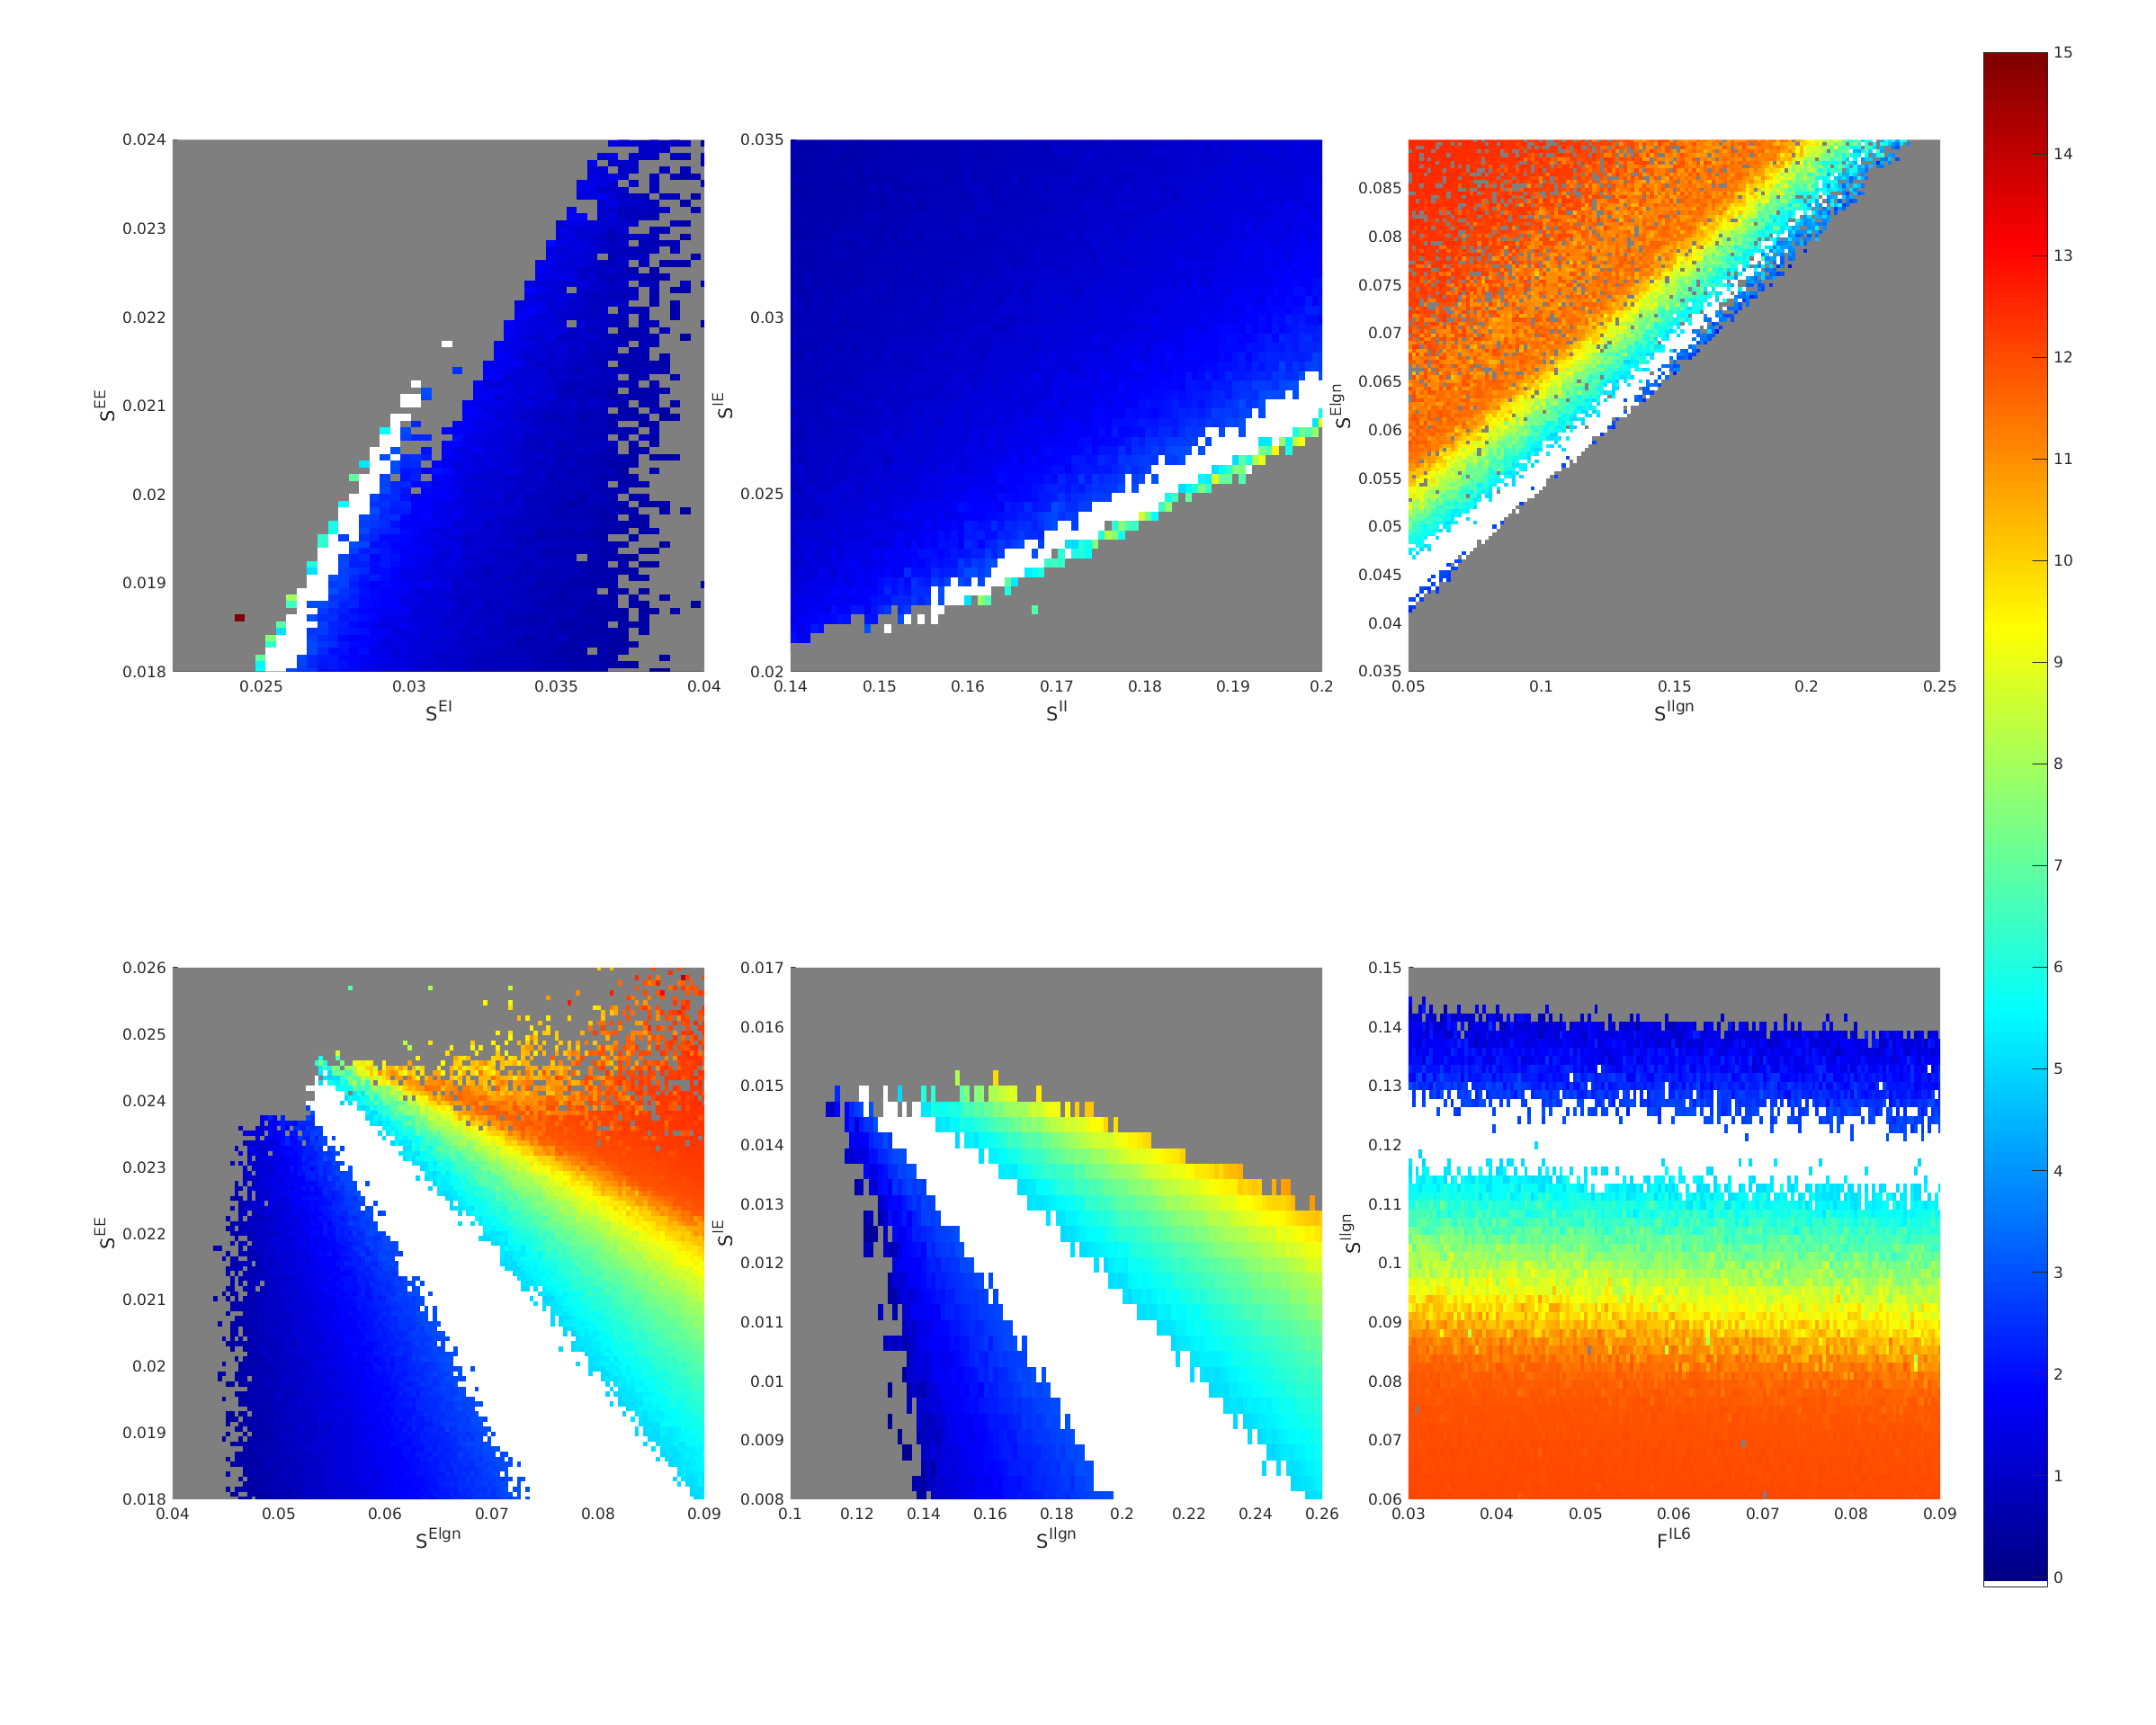

Fig1 = figure('Name','OtherSlices','units','normalized','outerposition',[0 0 .80 1]);

ha = tight_subplot(Panel1,Panel2,[.07 .04],[.08 .03],[.08 .1]);
AxShow = [0.022 0.04 0.018 0.024;
          0.14 0.2 0.02 0.035;
          0.05 0.25 0.035 0.09;
          0.04 0.09 0.018 0.026
          0.1 0.26 0.008 0.017
          0.03 0.09 0.06 0.15];
for RowInd = 1:Panel1
    for ColInd = 1:Panel2
        ParInd1U = ParInd1(Panel2*(RowInd-1)+ColInd);
        ParInd2U = ParInd2(Panel2*(RowInd-1)+ColInd);
        ParName1 = ParName{ParInd1U};
        ParName2 = ParName{ParInd2U};
        ParRan1 = FreeParRan{ParInd1U};
        ParRan2 = FreeParRan{ParInd2U};
        
        
        CurrentPanelFile = sprintf('FigD4_%s%s.mat',ParName1,ParName2);
        if isfile([DataFolder CurrentPanelFile])
        load(CurrentPanelFile, 'ContourData_7D')
        else 
            continue
        end

        % First axis for fr
        axes(ha(Panel2*(RowInd-1)+ColInd));
        ax1a = gca;
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
        %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentBlowup = squeeze(logical(ContourData_7D.FailIndi(:,:)));
        CurrentSteady = squeeze(~ContourData_7D.ConvIndi(:,:));
        FailMap = CurrentBlowup | CurrentSteady;
        CurrentFrEShow = CurrentFrE;
        CurrentFrEShow(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        CurrentFrEShow(FailMap) = nan;
        
        imagesc(ParRan2,ParRan1, CurrentFrEShow)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet]; 
        colormap(ax1a,cmap);  caxis([-0.1 15]); %colorbar;
        % set ticks, labels, titles, etc for axis1.
        ParNameShow1 = ParNameShow{ParInd1U};
        ParNameShow2 = ParNameShow{ParInd2U};
        ax = gca;
        ax.YAxis.FontSize = 13;
        ylabel(ParNameShow1,'FontSize',16)
        ax.XAxis.FontSize = 13;
        xlabel(ParNameShow2,'FontSize',16);
        
        axis square
        axis tight
        
        
        % second axis for blowup+unsteady
        GreyHem = 0.5*ones(size(CurrentFrE));
        originalSize = get(ax1a, 'Position');
        ax1b = axes('Position',originalSize); 
        hold on       
        GreyHemAlpha = double(FailMap);
        im1b = imagesc(ParRan2,ParRan1,GreyHem);
        im1b.AlphaData = GreyHemAlpha; % change this value to change the foreground image transparency
        axis square;
        
        
        %link axes
        linkaxes([ax1a,ax1b])
        %%Hide the top axes
        ax1b.Visible = 'off';
        ax1b.XTick = [];
        ax1b.YTick = [];
        set(ax1b,'YDir','normal')
        axis(AxShow(Panel2*(RowInd-1)+ColInd,:))
        
        %add differenct colormap to different data if you wish      
        colormap(ax1b,[0.5,0.5,0.5])
        
            if ColInd == Panel2
                if RowInd == 1
                    Pos1 = get(gca,'Position');
                elseif RowInd == Panel1
                    Pos2 = get(gca,'Position');
                end
            end
            
    end
end

cbr = colorbar(ax1a, 'Position', [Pos2(1)+Pos2(3)+0.02  Pos2(2)  0.03  Pos1(2)+Pos1(4)-Pos2(2)]);
caxis([0 15])
set(cbr,'YTick',0:15,'FontSize',13)